%Main File


n =      1     1     1     1     5
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     4     1     1     1     3


n =      4     1     1     1     3
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     5


n =      3     1     1     1     4
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     5     1     1     1     1


%Demo Model
n_population = 9;
n_pod_size = 3;
n_time = 150;
M_airtight = zeros(n_population, n_population);
M_pod_n = ones(n_pod_size, n_pod_size) - eye(n_pod_size);

for i = 1:(ceil(n_population/n_pod_size))+1
    slice_begin = (i - 1) * n_pod_size + 1;
    slice_end = slice_begin + n_pod_size - 1;
    if slice_end > n_population
        slice_end = n_population;
        M_pod_n = ones((slice_end-slice_begin)+1, (slice_end-slice_begin)+1) - eye((slice_end-slice_begin)+1);
    end
    M_airtight(slice_begin:slice_end, slice_begin:slice_end) = M_pod_n;
end

Graph_airtight = graph(M_airtight)

Graph_airtight =   graph with properties:

    Edges: [9×2 table]
    Nodes: [9×0 table]


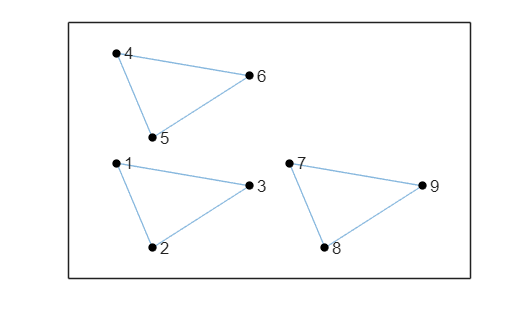

figure(); 
h = plot(Graph_airtight, 'NodeColor', 'k', 'LineWidth', 0.1);
layout(h, 'force', 'WeightEffect', 'inverse')